**Program-1 and Result:**

clc;
clear all;

Import the Base Image

[fname, path]=uigetfile('*.*','Please select a Base file where you want to hide message:');

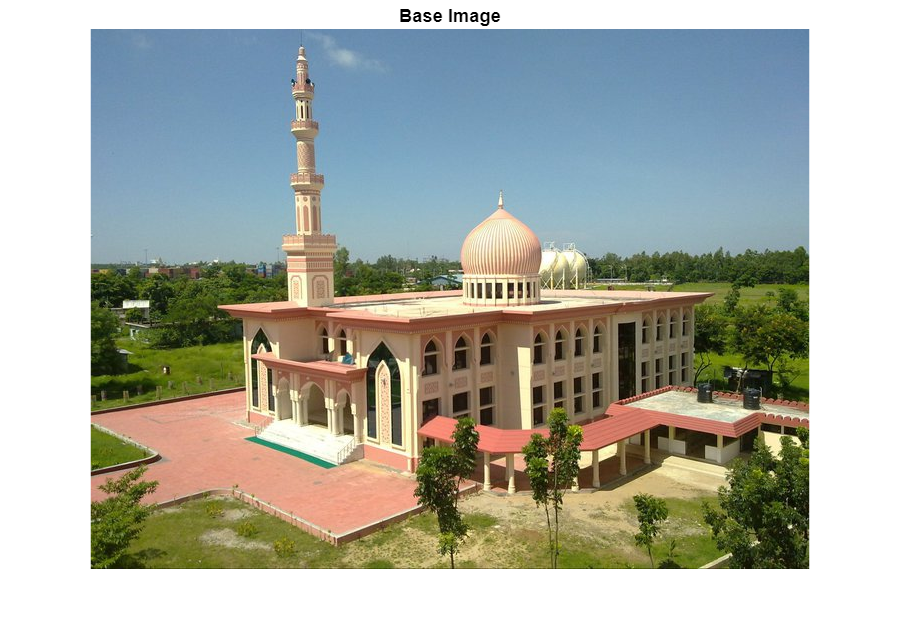

fname=strcat(path,fname);
[Base]=imread(fname);
figure
imshow(Base);
title('Base Image')

Import the Message Image and convert to Binary Image

[fname, path]=uigetfile('*.*','Please select a file which you want to hide:');
fname=strcat(path,fname);
[Message]=imread(fname);
Msg = imbinarize(rgb2gray(Message));

'imbinarize' requires Image Processing Toolbox.

figure;
imshow(Msg);
title('Hidden message');

Resize the message and base image to same size

Msg = imresize(Msg,size(Base(:,:,1)));

Select a bit plane and change it to our message signal

New = Base;
New(:,:,1) = bitset(New(:,:,1),1,Msg);

Save the Image file

figure
imshow(New);
title('Base Image with hidden message')
figure;
subplot(121)
imshow(Base);
title('Base Picture')
subplot(122)
imshow(New)
title('New Picture');
imwrite(New,'3.1_MsgIm.bmp');